# Analyzing Movie Ratings via SVD

In this notebook we're going to be working with a subset the MovieLens25M dataset.  The original dataset ([https://grouplens.org/datasets/movielens/25m/](https://grouplens.org/datasets/movielens/25m/)) contains

- 25 million ratings 

- from 162,000 users

- on 62,000 movies

The dataset was generated on November 21st, 2019, so it is pretty current.  In this activity, we're going to be using a reduced subset of this data that only includes popular movies (that have been rated at least 1000 times) and users that have rated lots of movies (at least 500).  This leaves us with

- 7.1 million ratings

- from 9,663 users

- on 3,790 movies

The goals of this activity are threefold.

- To work with a different type of data than images or temperatures (here we will be working with ratings).  Applying the tools you have learned in this module to different domains will help solidify your learning, help you see connections, and potentially get you excited for your module 1 project.

- To see how SVD can be used to examine the important trends in your data (since we had lots of practice with using the EVD on the overnight).

- To have some fun!

To get started, we're going to load the data and display a little bit of the data.  Please see the comments in the code for some more information.

load('movielens25m.mat');
sizeOfMovies = size(movies)

sizeOfMovies =         3790           3


% the cell array `movies` is 3706 by 3.  Each of the 3706 entries correspopnds to a
% particular movie, and along the second dimension the entries correspond to the movie ID,
% the movie title, and the movie genre
%
% Here we extract the information about the first movie in the dataset
[movieId, movieTitle, movieGenre] = movies{1,:}

movieId = int64
1

movieTitle = 'Toy Story (1995)'

movieGenre = 'Adventure|Animation|Children|Comedy|Fantasy'


ratingsSize = size(ratings)

ratingsSize =         9663        3790


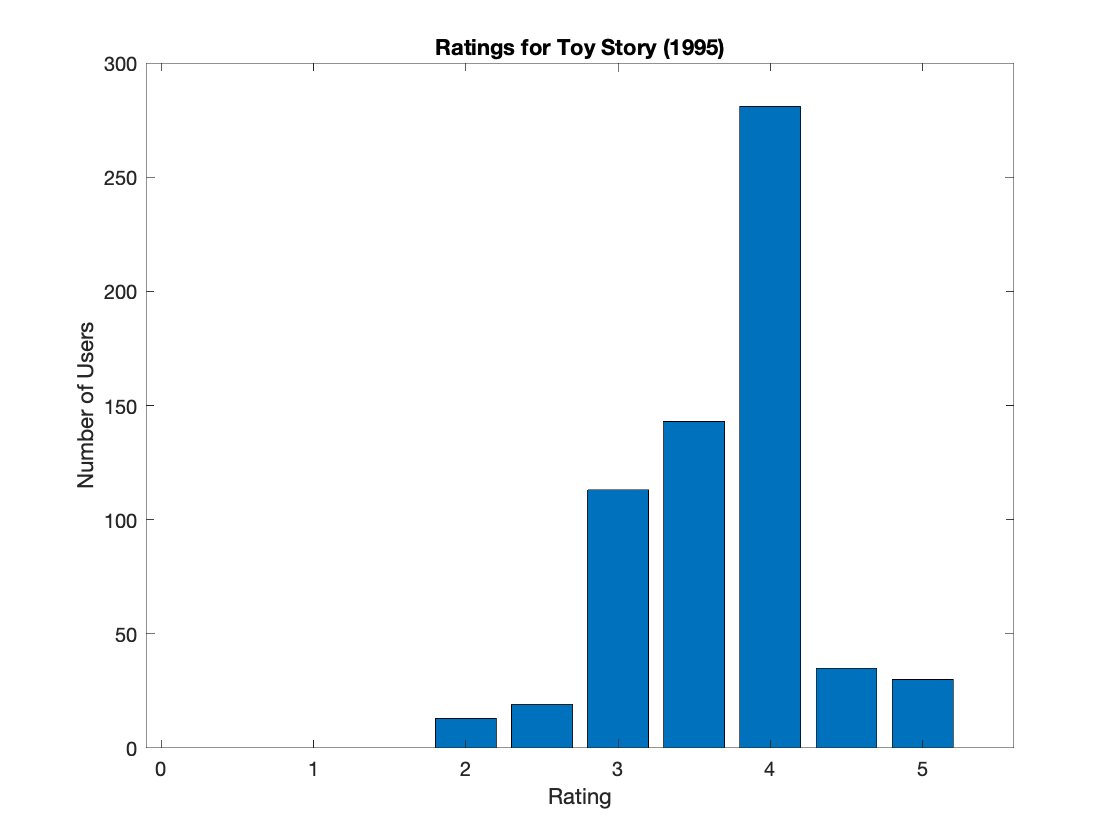

% the matrix `ratings` is 6040 by 3706 and encodes the rating that a
% particular user (row) gave to a particular movie (column).  The ratings
% are 1, 2, 3, 4, or 5 stars or the special value NaN (not a number) if the
% user didn't rate that particular movie.
%
% Let's look at the ratings that were given to the first movie in the
% dataset, which as we saw is Toy Story.  We can do this using the histc
% function (we'll ignore missing values in this analysis)
possibleRatings = [0.5:0.5:5];
nRatings = histc(ratings(1,:), possibleRatings);
figure;
bar(possibleRatings, nRatings);
xlabel('Rating');
ylabel('Number of Users');
title(['Ratings for ', movieTitle])

Okay, yeah that was a pretty great movie.  Let's check out a less good movie, Anaconda.  Highly recommended!!  Look at this cast [https://www.imdb.com/title/tt0118615/fullcredits](https://www.imdb.com/title/tt0118615/fullcredits) !!!

anacondaIndex = 850;
[movieId, movieTitle, movieGenre] = movies{anacondaIndex,:}

movieId = int64
1499

movieTitle = 'Anaconda (1997)'

movieGenre = 'Action|Adventure|Thriller'

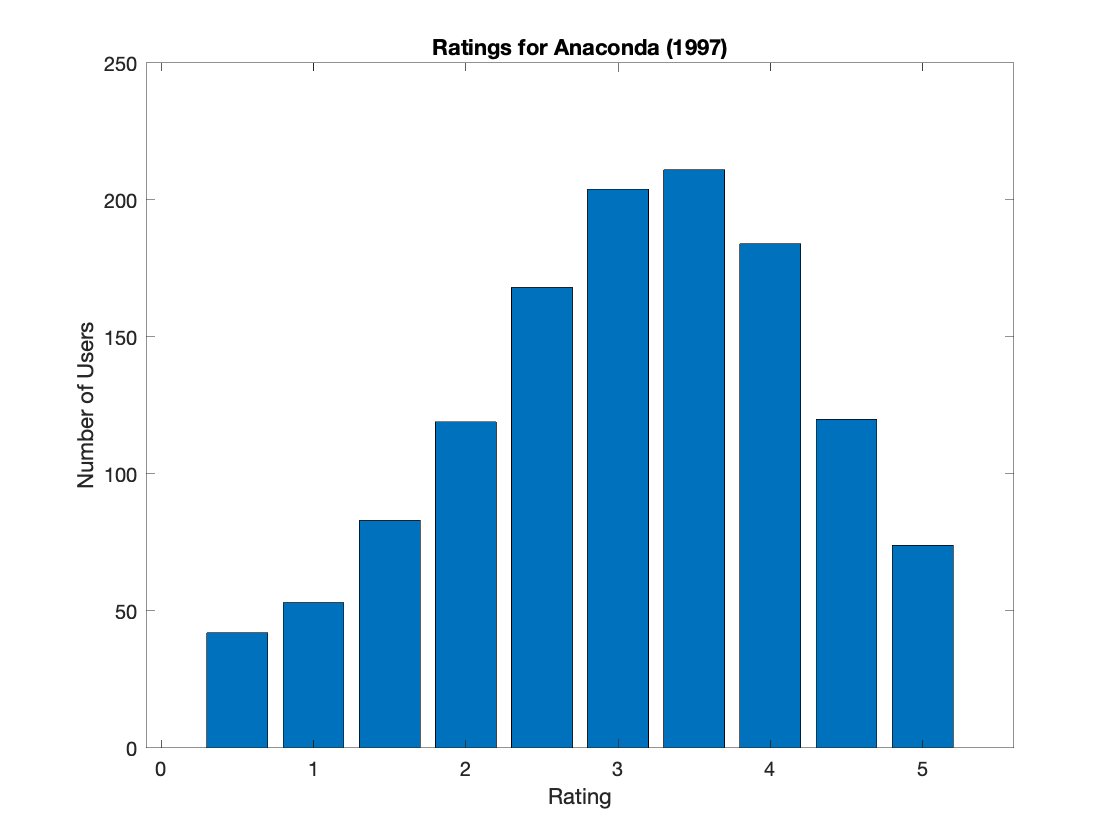

nRatings = histc(ratings(anacondaIndex,:), possibleRatings);
figure;
bar(possibleRatings, nRatings);
xlabel('Rating');
ylabel('Number of Users');
title(['Ratings for ', movieTitle])

## Cleaning up the Data

As you probably guessed, we're going to be applying SVD to this data.  Before we start analyzing this data, we're going to do a few things to make the problem a bit easier to handle.  First we're going to have to deal with the fact that we have a bunch of missing values in our ratings matrix (i.e., movies that particular users did not rate).  The step of filling in missing values is called **data imputation**.  There are many ways to do this, but we've chosen a particularly easy strategy of simply replacing any ratings with the average rating of that particular movie (e.g., if a user didn't rate Toy Story, we would fill it in with the average rating of Toy Story based on the other users in the dataset who actually rated that movie).

ratingsFilled = fillmissing(ratings, 'constant', nanmean(ratings));

As a final data cleaning step, we're going to subtract out the mean of each row.  This will control for the fact that users vary considerably in how the numerical score they assign to movies (e.g., one user's 3 may be more comparable to amother user's 1).

ratingsMeanCentered = ratingsFilled - mean(ratingsFilled,2);

## Framing the Problem Using SVD

Next, let's think about how SVD might help us to analyze this dataset.  Suppose we compute the SVD of the matrix `ratingsMeanCentered`.  Let's use $\mathbf{u_1}$ to refer to the first left singular vector, $\mathbf{v_1}$ to refer to the first right singular vector, and $\sigma_1$ to refer to the first singular value (let's assume that the first pair of singular vectors has the largest singular vector).

### **Exercise**

Before running any other code in this notebook, answer the following questions regarding the first pair of singular vectors.

- What are the sizes of $\mathbf{u_1}$ and $\mathbf{v_1}$?  What do each of the dimensions of $\mathbf{u_1}$ correspond to?  How about each dimension of $\mathbf{v_1}$?

- In 15.3.8 we talked about compressing the original matrix down to m + n + 1 values.  If we think of $\mathbf{u_1}, \mathbf{v_1}, \sigma_1$ as the compressed version of ratings data, how would we reconstruct the ratings data using $\mathbf{u_1}, \mathbf{v_1}, \sigma_1$ (you essentially did this already, we're hoping you can recall this fact from earlier and apply it here).

- We can think of $\mathbf{v_1}$ as encoding the dominant trend that explains the ratings of each movie.  For this dataset, what might this correspond to?

- We can think of $\mathbf{u_1}$ as encoding the dominant trend that explains the ratings by each usere.  For this dataset, what might this correspond to?  Keep in mind we have already subtracted out the mean of each user.  It might be helpful to expand your formula from problem 2 to see how $\mathbf{u_1}, \mathbf{v_1}, \sigma_1$ interact with each other.

Now we're going to compute the SVD.  We'll just compute the 10 pairs of left and right singular vectors with the largest singular values.

[U, Sigma, V] = svds(ratingsMeanCentered, 10);

## Examining the Right Singular Vectors

Now that we've computed our singular vectors, let's see if we can make sense of them.  It turns out that the right singular vectors (the ones that have to do with movies) are generally more interpretable than the left singular vectors (the ones that have to do with users).  We'll start out  by looking at each right singular vector.

### **Exercise**

Before running the code, think through the following question with your table-mates.

What might you do in order to make sense of what a particular right singular vector represents?  Consider things like examining small or large values, looking for correlations, etc.  There's not only one right answer, so throw out some ideas and try to think through what examining a particular aspect of the vector might tell you.

(we'll leave a little space to make it easier not to look at what we did)

### Looking at Large and Small Values

One simple way to understand the right singular vectors is to look at the largest and smallest components of each vector.  This will tell us which movies are either most strongly (positively) and most strongly (negatively) associated with this component.  In the code below, we'll print out the title, genre, and component of the 10 movies that are most positively and most negatively associated with each right singular vector.  **Exercise: Based on these outputs, can you tell a story about what the singular vector represents?**

for i = 1 : 10
    disp(['Component ', num2str(i)]);
    getHighAndLowMovies(V(:,i), movies)
end

Component 1


ans = 20×3 cell array
    {'Usual Suspects, The (1995)'                    }    {'Crime|Mystery|Thriller'     }    {[ 0.0309]}
    {'12 Angry Men (1957)'                           }    {'Drama'                      }    {[ 0.0310]}
    {'Seven Samurai (Shichinin no samurai) (1954)'   }    {'Action|Adventure|Drama'     }    {[ 0.0312]}
    {'Pulp Fiction (1994)'                           }    {'Comedy|Crime|Drama|Thriller'}    {[ 0.0318]}
    {'Godfather: Part II, The (1974)'                }    {'Crime|Drama'                }    {[ 0.0318]}
    {'Band of Brothers (2001)'                       }    {'Action|Drama|War'           }    {[ 0.0349]}
    {'Godfather, The (1972)'                         }    {'Crime|Drama'                }    {[ 0.0353]}
    {'Shawshank Redemption, The (1994)'              }    {'Crime|Drama'                }    {[ 0.0353]}
    {'Planet Earth (2006)'                           }    {'Documentary'                }    {[ 0.0370]}
    {'Planet Earth II (2016)'    

Component 2


ans = 20×3 cell array
    {'Matrix Reloaded, The (2003)'                        }    {'Action|Adventure|Sci-Fi|Thriller|IMAX'              }    {[ 0.0741]}
    {'Jurassic Park (1993)'                               }    {'Action|Adventure|Sci-Fi|Thriller'                   }    {[ 0.0749]}
    {'Star Wars: Episode II - Attack of the Clones (2002)'}    {'Action|Adventure|Sci-Fi|IMAX'                       }    {[ 0.0765]}
    {'Titanic (1997)'                                     }    {'Drama|Romance'                                      }    {[ 0.0766]}
    {'Shrek (2001)'                                       }    {'Adventure|Animation|Children|Comedy|Fantasy|Romance'}    {[ 0.0770]}
    {'Armageddon (1998)'                                  }    {'Action|Romance|Sci-Fi|Thriller'                     }    {[ 0.0775]}
    {'Men in Black (a.k.a. MIB) (1997)'                   }    {'Action|Comedy|Sci-Fi'                               }    {[ 0.0783]}
    {'Forrest Gump (1994)'              

Component 3


ans = 20×3 cell array
    {'Thor (2011)'                                      }    {'Action|Adventure|Drama|Fantasy|IMAX'                      }    {[ 0.0568]}
    {'Iron Man (2008)'                                  }    {'Action|Adventure|Sci-Fi'                                  }    {[ 0.0572]}
    {'Pirates of the Caribbean: Dead Man's Chest (2006)'}    {'Action|Adventure|Fantasy'                                 }    {[ 0.0583]}
    {'X-Men: The Last Stand (2006)'                     }    {'Action|Sci-Fi|Thriller'                                   }    {[ 0.0616]}
    {'Pirates of the Caribbean: At World's End (2007)'  }    {'Action|Adventure|Comedy|Fantasy'                          }    {[ 0.0619]}
    {'Avengers, The (2012)'                             }    {'Action|Adventure|Sci-Fi|IMAX'                             }    {[ 0.0636]}
    {'Avatar (2009)'                                    }    {'Action|Adventure|Sci-Fi|IMAX'                             }    {[ 0.0639]}
    {'Iron M

Component 4


ans = 20×3 cell array
    {'Air Force One (1997)'                }    {'Action|Thriller'                      }    {[ 0.0539]}
    {'Sleepless in Seattle (1993)'         }    {'Comedy|Drama|Romance'                 }    {[ 0.0542]}
    {'Pearl Harbor (2001)'                 }    {'Action|Drama|Romance|War'             }    {[ 0.0543]}
    {'You've Got Mail (1998)'              }    {'Comedy|Romance'                       }    {[ 0.0565]}
    {'Twister (1996)'                      }    {'Action|Adventure|Romance|Thriller'    }    {[ 0.0594]}
    {'Top Gun (1986)'                      }    {'Action|Romance'                       }    {[ 0.0599]}
    {'Ghost (1990)'                        }    {'Comedy|Drama|Fantasy|Romance|Thriller'}    {[ 0.0600]}
    {'Independence Day (a.k.a. ID4) (1996)'}    {'Action|Adventure|Sci-Fi|Thriller'     }    {[ 0.0714]}
    {'Pretty Woman (1990)'                 }    {'Comedy|Romance'                       }    {[ 0.0731]}
    {'Armageddon (1998)'         

Component 5


ans = 20×3 cell array
    {'Matrix, The (1999)'                    }    {'Action|Sci-Fi|Thriller'                         }    {[ 0.0634]}
    {'Fight Club (1999)'                     }    {'Action|Crime|Drama|Thriller'                    }    {[ 0.0639]}
    {'Rock, The (1996)'                      }    {'Action|Adventure|Thriller'                      }    {[ 0.0645]}
    {'Con Air (1997)'                        }    {'Action|Adventure|Thriller'                      }    {[ 0.0646]}
    {'The Devil's Advocate (1997)'           }    {'Drama|Mystery|Thriller'                         }    {[ 0.0651]}
    {'Predator (1987)'                       }    {'Action|Sci-Fi|Thriller'                         }    {[ 0.0660]}
    {'Die Hard: With a Vengeance (1995)'     }    {'Action|Crime|Thriller'                          }    {[ 0.0698]}
    {'Fifth Element, The (1997)'             }    {'Action|Adventure|Comedy|Sci-Fi'                 }    {[ 0.0710]}
    {'From Dusk Till Dawn (1996)'         

Component 6


ans = 20×3 cell array
    {'Predator (1987)'                                                               }    {'Action|Sci-Fi|Thriller'            }    {[ 0.0670]}
    {'Back to the Future (1985)'                                                     }    {'Adventure|Comedy|Sci-Fi'           }    {[ 0.0699]}
    {'Die Hard (1988)'                                                               }    {'Action|Crime|Thriller'             }    {[ 0.0713]}
    {'Terminator, The (1984)'                                                        }    {'Action|Sci-Fi|Thriller'            }    {[ 0.0728]}
    {'Terminator 2: Judgment Day (1991)'                                             }    {'Action|Sci-Fi'                     }    {[ 0.0764]}
    {'Star Wars: Episode IV - A New Hope (1977)'                                     }    {'Action|Adventure|Sci-Fi'           }    {[ 0.0777]}
    {'Raiders of the Lost Ark (Indiana Jones and the Raiders of the Lost Ark) (1981)'}    {'Action|Adventure'     

Component 7


ans = 20×3 cell array
    {'Billy Madison (1995)'                              }    {'Comedy'                 }    {[ 0.0849]}
    {'Austin Powers in Goldmember (2002)'                }    {'Comedy'                 }    {[ 0.0850]}
    {'Scary Movie (2000)'                                }    {'Comedy|Horror'          }    {[ 0.0876]}
    {'Zoolander (2001)'                                  }    {'Comedy'                 }    {[ 0.0877]}
    {'Austin Powers: The Spy Who Shagged Me (1999)'      }    {'Action|Adventure|Comedy'}    {[ 0.0932]}
    {'Ace Ventura: When Nature Calls (1995)'             }    {'Comedy'                 }    {[ 0.0937]}
    {'Dumb & Dumber (Dumb and Dumber) (1994)'            }    {'Adventure|Comedy'       }    {[ 0.0948]}
    {'Austin Powers: International Man of Mystery (1997)'}    {'Action|Adventure|Comedy'}    {[ 0.0962]}
    {'Happy Gilmore (1996)'                              }    {'Comedy'                 }    {[ 0.1004]}
    {'Ace Ventura: Pet Detective 

Component 8


ans = 20×3 cell array
    {'Mrs. Doubtfire (1993)'                                     }    {'Comedy|Drama'                                   }    {[ 0.0615]}
    {'Braveheart (1995)'                                         }    {'Action|Drama|War'                               }    {[ 0.0620]}
    {'Toy Story (1995)'                                          }    {'Adventure|Animation|Children|Comedy|Fantasy'    }    {[ 0.0649]}
    {'Shawshank Redemption, The (1994)'                          }    {'Crime|Drama'                                    }    {[ 0.0703]}
    {'Titanic (1997)'                                            }    {'Drama|Romance'                                  }    {[ 0.0760]}
    {'Home Alone (1990)'                                         }    {'Children|Comedy'                                }    {[ 0.0766]}
    {'Lion King, The (1994)'                                     }    {'Adventure|Animation|Children|Drama|Musical|IMAX'}    {[ 0.0769]}
    {'Jurassic Park

Component 9


ans = 20×3 cell array
    {'Harry Potter and the Prisoner of Azkaban (2004)'                                               }    {'Adventure|Fantasy|IMAX'            }    {[ 0.0696]}
    {'Spirited Away (Sen to Chihiro no kamikakushi) (2001)'                                          }    {'Adventure|Animation|Fantasy'       }    {[ 0.0696]}
    {'Harry Potter and the Chamber of Secrets (2002)'                                                }    {'Adventure|Fantasy'                 }    {[ 0.0773]}
    {'Rocky Horror Picture Show, The (1975)'                                                         }    {'Comedy|Horror|Musical|Sci-Fi'      }    {[ 0.0799]}
    {'Nightmare Before Christmas, The (1993)'                                                        }    {'Animation|Children|Fantasy|Musical'}    {[ 0.0814]}
    {'Harry Potter and the Sorcerer's Stone (a.k.a. Harry Potter and the Philosopher's Stone) (2001)'}    {'Adventure|Children|Fantasy'        }    {[ 0.0850]}
    {'Lord of the 

Component 10


ans = 20×3 cell array
    {'Princess Bride, The (1987)'                               }    {'Action|Adventure|Comedy|Fantasy|Romance'}    {[ 0.0837]}
    {'Star Wars: Episode III - Revenge of the Sith (2005)'      }    {'Action|Adventure|Sci-Fi'                }    {[ 0.0949]}
    {'Star Wars: Episode I - The Phantom Menace (1999)'         }    {'Action|Adventure|Sci-Fi'                }    {[ 0.0965]}
    {'Star Wars: Episode II - Attack of the Clones (2002)'      }    {'Action|Adventure|Sci-Fi|IMAX'           }    {[ 0.1111]}
    {'Lord of the Rings: The Return of the King, The (2003)'    }    {'Action|Adventure|Drama|Fantasy'         }    {[ 0.1140]}
    {'Lord of the Rings: The Two Towers, The (2002)'            }    {'Adventure|Fantasy'                      }    {[ 0.1245]}
    {'Star Wars: Episode V - The Empire Strikes Back (1980)'    }    {'Action|Adventure|Sci-Fi'                }    {[ 0.1296]}
    {'Lord of the Rings: The Fellowship of the Ring, The (2001)'}    {'Adventure|F

## Examining the Left Singular Vectors

Now we're going to check out the left singular vectors.

### **Exercise**

Before running the code, think through the following question with your table-mates.

What might you do in order to make sense of what a particular left singular vector represents?  Consider things like examining small or large values, looking for correlations, etc.  There's not only one right answer, so throw out some ideas and try to think through what examining a particular aspect of the vector might tell you.

(we'll leave a little space to make it easier not to look at what we did)

### Looking at Large and Small Values

Similarly to what we did for the right singular vectors, let's take a look at large (positive) and small (negative) components of each singular vector.  Instead of looking at the top 10 and bottom 10, we're instead going to look at the single highest and single lowest component (each of which correspond to a user).  For that user, we're going to show a sampling of movies that the user rated (focusing on the top 10 and bottom 10 ratings for that particular user). ** Exercise: Given what you know about the corresponding right singular vector, try to make sense of the users that are at either extreme of the left singular vectors.**

for i = 1 : 10
    [~, highestUserIndex] = max(U(:,i));
    [~, lowestUserIndex] = min(U(:,i));
    disp('');
    disp(['Component ', num2str(i)]);
    disp('The user with the largest component rated the following movies as high and low');
    getHighAndLowUserRatings(highestUserIndex, movies, ratings)
    disp('The user with the smallest (probably negative) component rated the following movies as high and low');
    getHighAndLowUserRatings(lowestUserIndex, movies, ratings)
end

Component 1


The user with the largest component rated the following movies as high and low


ans = 20×2 cell array
    {'Thor: Ragnarok (2017)'                                                          }    {[     5]}
    {'Louis C.K.: Live at The Comedy Store (2015)'                                    }    {[     5]}
    {'Tomorrowland (2015)'                                                            }    {[     5]}
    {'Inside Out (2015)'                                                              }    {[     5]}
    {'Creed (2015)'                                                                   }    {[     5]}
    {'Hunt for the Wilderpeople (2016)'                                               }    {[     5]}
    {'Planet Earth (2006)'                                                            }    {[     5]}
    {'The Lego Batman Movie (2017)'                                                   }    {[     5]}
    {'Baby Driver (2017)'                                                             }    {[     5]}
    {'The Shape of Water (2017)'                            

The user with the smallest (probably negative) component rated the following movies as high and low


ans = 20×2 cell array
    {'Law Abiding Citizen (2009)'        }    {[     5]}
    {'Avatar (2009)'                     }    {[     5]}
    {'Sherlock Holmes (2009)'            }    {[     5]}
    {'Shutter Island (2010)'             }    {[     5]}
    {'Inception (2010)'                  }    {[     5]}
    {'Expendables, The (2010)'           }    {[     5]}
    {'127 Hours (2010)'                  }    {[     5]}
    {'Iron Man 3 (2013)'                 }    {[     5]}
    {'Interstellar (2014)'               }    {[     5]}
    {'Furious 7 (2015)'                  }    {[     5]}
    {'Father of the Bride Part II (1995)'}    {[0.5000]}
    {'Heat (1995)'                       }    {[0.5000]}
    {'Sudden Death (1995)'               }    {[0.5000]}
    {'GoldenEye (1995)'                  }    {[0.5000]}
    {'Dracula: Dead and Loving It (1995)'}    {[0.5000]}
    {'Cutthroat Island (1995)'           }    {[0.5000]}


Component 2


The user with the largest component rated the following movies as high and low


ans = 20×2 cell array
    {'The Intern (2015)'                                                        }    {[     5]}
    {'Straight Outta Compton (2015)'                                            }    {[     5]}
    {'Everest (2015)'                                                           }    {[     5]}
    {'Hotel Transylvania 2 (2015)'                                              }    {[     5]}
    {'Creed (2015)'                                                             }    {[     5]}
    {'Finding Dory (2016)'                                                      }    {[     5]}
    {'Captain Fantastic (2016)'                                                 }    {[     5]}
    {'Hacksaw Ridge (2016)'                                                     }    {[     5]}
    {'Arrival (2016)'                                                           }    {[     5]}
    {'Rogue One: A Star Wars Story (2016)'                                      }    {[     5]}
    {'Doom (2005)'

The user with the smallest (probably negative) component rated the following movies as high and low


ans = 20×2 cell array
    {'Matrix, The (1999)'                                       }    {[     5]}
    {'Eyes Wide Shut (1999)'                                    }    {[     5]}
    {'Lord of the Rings: The Fellowship of the Ring, The (2001)'}    {[     5]}
    {'Kill Bill: Vol. 1 (2003)'                                 }    {[     5]}
    {'Kill Bill: Vol. 2 (2004)'                                 }    {[     5]}
    {'No Country for Old Men (2007)'                            }    {[     5]}
    {'There Will Be Blood (2007)'                               }    {[     5]}
    {'Grand Budapest Hotel, The (2014)'                         }    {[     5]}
    {'Interstellar (2014)'                                      }    {[     5]}
    {'Dunkirk (2017)'                                           }    {[     5]}
    {'Grumpier Old Men (1995)'                                  }    {[0.5000]}
    {'Babe (1995)'                                              }    {[0.5000]}
    {'Mortal Komba

Component 3


The user with the largest component rated the following movies as high and low


ans = 20×2 cell array
    {'Star Wars: Episode V - The Empire Strikes Back (1980)'                         }    {[5]}
    {'Raiders of the Lost Ark (Indiana Jones and the Raiders of the Lost Ark) (1981)'}    {[5]}
    {'Lawrence of Arabia (1962)'                                                     }    {[5]}
    {'Star Wars: Episode VI - Return of the Jedi (1983)'                             }    {[5]}
    {'Groundhog Day (1993)'                                                          }    {[5]}
    {'Ben-Hur (1959)'                                                                }    {[5]}
    {'Hunt for Red October, The (1990)'                                              }    {[5]}
    {'Saving Private Ryan (1998)'                                                    }    {[5]}
    {'Ronin (1998)'                                                                  }    {[5]}
    {'Goldfinger (1964)'                                                             }    {[5]}
    {'Grumpier Old

The user with the smallest (probably negative) component rated the following movies as high and low


ans = 20×2 cell array
    {'2046 (2004)'                                           }    {[     5]}
    {'Old Boy (2003)'                                        }    {[     5]}
    {'Apocalypto (2006)'                                     }    {[     5]}
    {'Pan's Labyrinth (Laberinto del fauno, El) (2006)'      }    {[     5]}
    {'There Will Be Blood (2007)'                            }    {[     5]}
    {'Let the Right One In (LÃ¥t den rÃ¤tte komma in) (2008)'}    {[     5]}
    {'I Saw the Devil (Akmareul boatda) (2010)'              }    {[     5]}
    {'Mission: Impossible - Ghost Protocol (2011)'           }    {[     5]}
    {'Mission: Impossible - Rogue Nation (2015)'             }    {[     5]}
    {'Mad Max: Fury Road (2015)'                             }    {[     5]}
    {'Congo (1995)'                                          }    {[0.5000]}
    {'Coneheads (1993)'                                      }    {[0.5000]}
    {'Demolition Man (1993)'                          

Component 4


The user with the largest component rated the following movies as high and low


ans = 20×2 cell array
    {'Mission: Impossible - Ghost Protocol (2011)'      }    {[     5]}
    {'Impossible, The (Imposible, Lo) (2012)'           }    {[     5]}
    {'Star Trek Into Darkness (2013)'                   }    {[     5]}
    {'Man of Steel (2013)'                              }    {[     5]}
    {'Godzilla (2014)'                                  }    {[     5]}
    {'Guardians of the Galaxy (2014)'                   }    {[     5]}
    {'Star Wars: Episode VII - The Force Awakens (2015)'}    {[     5]}
    {'The Age of Adaline (2015)'                        }    {[     5]}
    {'The Man from U.N.C.L.E. (2015)'                   }    {[     5]}
    {'Dunkirk (2017)'                                   }    {[     5]}
    {'Heat (1995)'                                      }    {[0.5000]}
    {'Nixon (1995)'                                     }    {[0.5000]}
    {'Casino (1995)'                                    }    {[0.5000]}
    {'Get Shorty (1995)'                  

The user with the smallest (probably negative) component rated the following movies as high and low


ans = 20×2 cell array
    {'Primer (2004)'                                         }    {[     5]}
    {'Sideways (2004)'                                       }    {[     5]}
    {'Incredibles, The (2004)'                               }    {[     5]}
    {'Battle of Algiers, The (La battaglia di Algeri) (1966)'}    {[     5]}
    {'Aviator, The (2004)'                                   }    {[     5]}
    {'Sin City (2005)'                                       }    {[     5]}
    {'Batman Begins (2005)'                                  }    {[     5]}
    {'Constant Gardener, The (2005)'                         }    {[     5]}
    {'Lord of War (2005)'                                    }    {[     5]}
    {'Weather Man, The (2005)'                               }    {[     5]}
    {'Dracula: Dead and Loving It (1995)'                    }    {[0.5000]}
    {'Cutthroat Island (1995)'                               }    {[0.5000]}
    {'Mr. Holland's Opus (1995)'                      

Component 5


The user with the largest component rated the following movies as high and low


ans = 20×2 cell array
    {'Wolf of Wall Street, The (2013)'   }    {[     5]}
    {'American Hustle (2013)'            }    {[     5]}
    {'Interstellar (2014)'               }    {[     5]}
    {'The Expendables 3 (2014)'          }    {[     5]}
    {'John Wick (2014)'                  }    {[     5]}
    {'Nightcrawler (2014)'               }    {[     5]}
    {'Mad Max: Fury Road (2015)'         }    {[     5]}
    {'The Hateful Eight (2015)'          }    {[     5]}
    {'Big Short, The (2015)'             }    {[     5]}
    {'John Wick: Chapter Two (2017)'     }    {[     5]}
    {'Toy Story (1995)'                  }    {[0.5000]}
    {'Grumpier Old Men (1995)'           }    {[0.5000]}
    {'Father of the Bride Part II (1995)'}    {[0.5000]}
    {'Sabrina (1995)'                    }    {[0.5000]}
    {'Nixon (1995)'                      }    {[0.5000]}
    {'Get Shorty (1995)'                 }    {[0.5000]}


The user with the smallest (probably negative) component rated the following movies as high and low


ans = 20×2 cell array
    {'Shrek 2 (2004)'                        }    {[     5]}
    {'Before Sunset (2004)'                  }    {[     5]}
    {'Finding Neverland (2004)'              }    {[     5]}
    {'Charlie Brown Christmas, A (1965)'     }    {[     5]}
    {'Million Dollar Baby (2004)'            }    {[     5]}
    {'Hotel Rwanda (2004)'                   }    {[     5]}
    {'Notes on a Scandal (2006)'             }    {[     5]}
    {'How the Grinch Stole Christmas! (1966)'}    {[     5]}
    {'Juno (2007)'                           }    {[     5]}
    {'Toy Story 3 (2010)'                    }    {[     5]}
    {'Natural Born Killers (1994)'           }    {[0.5000]}
    {'Stargate (1994)'                       }    {[0.5000]}
    {'Ace Ventura: Pet Detective (1994)'     }    {[0.5000]}
    {'Mask, The (1994)'                      }    {[0.5000]}
    {'Threesome (1994)'                      }    {[0.5000]}
    {'Bad Taste (1987)'                      }    {[0.5000]}


Component 6


The user with the largest component rated the following movies as high and low


ans = 20×2 cell array
    {'Grand Budapest Hotel, The (2014)'          }    {[     5]}
    {'Captain America: The Winter Soldier (2014)'}    {[     5]}
    {'Predestination (2014)'                     }    {[     5]}
    {'John Wick (2014)'                          }    {[     5]}
    {'Big Hero 6 (2014)'                         }    {[     5]}
    {'Kingsman: The Secret Service (2015)'       }    {[     5]}
    {'Deadpool (2016)'                           }    {[     5]}
    {'Tomorrowland (2015)'                       }    {[     5]}
    {'Inside Out (2015)'                         }    {[     5]}
    {'Sicario (2015)'                            }    {[     5]}
    {'Jumanji (1995)'                            }    {[0.5000]}
    {'Grumpier Old Men (1995)'                   }    {[0.5000]}
    {'Waiting to Exhale (1995)'                  }    {[0.5000]}
    {'Tom and Huck (1995)'                       }    {[0.5000]}
    {'Sudden Death (1995)'                       }    {[0.5000]}
   

The user with the smallest (probably negative) component rated the following movies as high and low


ans = 20×2 cell array
    {'Seven (a.k.a. Se7en) (1995)'              }    {[     5]}
    {'Silence of the Lambs, The (1991)'         }    {[     5]}
    {'Pretty Woman (1990)'                      }    {[     5]}
    {'E.T. the Extra-Terrestrial (1982)'        }    {[     5]}
    {'Blair Witch Project, The (1999)'          }    {[     5]}
    {'Boys Don't Cry (1999)'                    }    {[     5]}
    {'Fight Club (1999)'                        }    {[     5]}
    {'Coyote Ugly (2000)'                       }    {[     5]}
    {'Memento (2000)'                           }    {[     5]}
    {'Donnie Darko (2001)'                      }    {[     5]}
    {'Judge Dredd (1995)'                       }    {[0.5000]}
    {'Naked Gun 33 1/3: The Final Insult (1994)'}    {[0.5000]}
    {'Hot Shots! Part Deux (1993)'              }    {[0.5000]}
    {'Kingpin (1996)'                           }    {[0.5000]}
    {'Maltese Falcon, The (1941)'               }    {[0.5000]}
    {'Ninotchka (1

Component 7


The user with the largest component rated the following movies as high and low


ans = 20×2 cell array
    {'Big Hero 6 (2014)'                                }    {[     5]}
    {'The Hobbit: The Battle of the Five Armies (2014)' }    {[     5]}
    {'Kingsman: The Secret Service (2015)'              }    {[     5]}
    {'Mad Max: Fury Road (2015)'                        }    {[     5]}
    {'Star Wars: Episode VII - The Force Awakens (2015)'}    {[     5]}
    {'Avengers: Age of Ultron (2015)'                   }    {[     5]}
    {'Furious 7 (2015)'                                 }    {[     5]}
    {'Kung Fury (2015)'                                 }    {[     5]}
    {'Spectre (2015)'                                   }    {[     5]}
    {'The Man from U.N.C.L.E. (2015)'                   }    {[     5]}
    {'There Will Be Blood (2007)'                       }    {[2.5000]}
    {'Beautician and the Beast, The (1997)'             }    {[     3]}
    {'Spice World (1997)'                               }    {[     3]}
    {'Cube (1997)'                        

The user with the smallest (probably negative) component rated the following movies as high and low


ans = 20×2 cell array
    {'Grand Budapest Hotel, The (2014)'       }    {[     5]}
    {'X-Men: Days of Future Past (2014)'      }    {[     5]}
    {'Ex Machina (2015)'                      }    {[     5]}
    {'Avengers: Age of Ultron (2015)'         }    {[     5]}
    {'Avengers: Infinity War - Part I (2018)' }    {[     5]}
    {'Avengers: Infinity War - Part II (2019)'}    {[     5]}
    {'X-Men: Apocalypse (2016)'               }    {[     5]}
    {'The Hateful Eight (2015)'               }    {[     5]}
    {'The Handmaiden (2016)'                  }    {[     5]}
    {'Mission: Impossible - Fallout (2018)'   }    {[     5]}
    {'Toy Story (1995)'                       }    {[0.5000]}
    {'Sense and Sensibility (1995)'           }    {[0.5000]}
    {'Ace Ventura: When Nature Calls (1995)'  }    {[0.5000]}
    {'Get Shorty (1995)'                      }    {[0.5000]}
    {'Babe (1995)'                            }    {[0.5000]}
    {'Clueless (1995)'                        } 

Component 8


The user with the largest component rated the following movies as high and low


ans = 20×2 cell array
    {'Wolf of Wall Street, The (2013)'                      }    {[4.5000]}
    {'Whiplash (2014)'                                      }    {[4.5000]}
    {'The Revenant (2015)'                                  }    {[4.5000]}
    {'Rogue One: A Star Wars Story (2016)'                  }    {[4.5000]}
    {'Casino (1995)'                                        }    {[     5]}
    {'Star Wars: Episode IV - A New Hope (1977)'            }    {[     5]}
    {'Carlito's Way (1993)'                                 }    {[     5]}
    {'Star Wars: Episode V - The Empire Strikes Back (1980)'}    {[     5]}
    {'Goodfellas (1990)'                                    }    {[     5]}
    {'Donnie Brasco (1997)'                                 }    {[     5]}
    {'Toy Story (1995)'                                     }    {[0.5000]}
    {'Grumpier Old Men (1995)'                              }    {[0.5000]}
    {'Father of the Bride Part II (1995)'                   }    {

The user with the smallest (probably negative) component rated the following movies as high and low


ans = 20×2 cell array
    {'Thor: Ragnarok (2017)'                    }    {[     5]}
    {'Guardians of the Galaxy 2 (2017)'         }    {[     5]}
    {'Captain America: Civil War (2016)'        }    {[     5]}
    {'Doctor Strange (2016)'                    }    {[     5]}
    {'X-Men: Apocalypse (2016)'                 }    {[     5]}
    {'Untitled Spider-Man Reboot (2017)'        }    {[     5]}
    {'Batman v Superman: Dawn of Justice (2016)'}    {[     5]}
    {'The Man from U.N.C.L.E. (2015)'           }    {[     5]}
    {'Wonder Woman (2017)'                      }    {[     5]}
    {'Incredibles 2 (2018)'                     }    {[     5]}
    {'Bullets Over Broadway (1994)'             }    {[0.5000]}
    {'Trainspotting (1996)'                     }    {[0.5000]}
    {'Perfect Storm, The (2000)'                }    {[0.5000]}
    {'Requiem for a Dream (2000)'               }    {[0.5000]}
    {'Holiday, The (2006)'                      }    {[0.5000]}
    {'Bridge to Te

Component 9


The user with the largest component rated the following movies as high and low


ans = 20×2 cell array
    {'Twilight Saga: New Moon, The (2009)'   }    {[     5]}
    {'Princess and the Frog, The (2009)'     }    {[     5]}
    {'Avatar (2009)'                         }    {[     5]}
    {'How to Train Your Dragon (2010)'       }    {[     5]}
    {'Clash of the Titans (2010)'            }    {[     5]}
    {'Inception (2010)'                      }    {[     5]}
    {'Tron: Legacy (2010)'                   }    {[     5]}
    {'Source Code (2011)'                    }    {[     5]}
    {'Puss in Boots (2011)'                  }    {[     5]}
    {'Prometheus (2012)'                     }    {[     5]}
    {'Usual Suspects, The (1995)'            }    {[0.5000]}
    {'Fair Game (1995)'                      }    {[0.5000]}
    {'Young Poisoner's Handbook, The (1995)' }    {[0.5000]}
    {'Jury Duty (1995)'                      }    {[0.5000]}
    {'One Flew Over the Cuckoo's Nest (1975)'}    {[0.5000]}
    {'Dead Poets Society (1989)'             }    {[0.5000]}


The user with the smallest (probably negative) component rated the following movies as high and low


ans = 20×2 cell array
    {'City Slickers (1991)'                                                           }    {[     5]}
    {'48 Hrs. (1982)'                                                                 }    {[     5]}
    {'Smokey and the Bandit (1977)'                                                   }    {[     5]}
    {'Mystic River (2003)'                                                            }    {[     5]}
    {'Presumed Innocent (1990)'                                                       }    {[     5]}
    {'History of Violence, A (2005)'                                                  }    {[     5]}
    {'No Country for Old Men (2007)'                                                  }    {[     5]}
    {'Taken (2008)'                                                                   }    {[     5]}
    {'True Grit (2010)'                                                               }    {[     5]}
    {'Hidden Figures (2016)'                                

Component 10


The user with the largest component rated the following movies as high and low


ans = 20×2 cell array
    {'Lookout, The (2007)'                                }    {[     5]}
    {'Transformers (2007)'                                }    {[     5]}
    {'Stardust (2007)'                                    }    {[     5]}
    {'Bourne Ultimatum, The (2007)'                       }    {[     5]}
    {'Superbad (2007)'                                    }    {[     5]}
    {'Dan in Real Life (2007)'                            }    {[     5]}
    {'Enchanted (2007)'                                   }    {[     5]}
    {'Juno (2007)'                                        }    {[     5]}
    {'In Bruges (2008)'                                   }    {[     5]}
    {'Forgetting Sarah Marshall (2008)'                   }    {[     5]}
    {'Ace Ventura: When Nature Calls (1995)'              }    {[0.5000]}
    {'Copycat (1995)'                                     }    {[0.5000]}
    {'Congo (1995)'                                       }    {[0.5000]}
    {'Beverly Hi

The user with the smallest (probably negative) component rated the following movies as high and low


ans = 20×2 cell array
    {'X-Men: The Last Stand (2006)'                                    }    {[     5]}
    {'Pursuit of Happyness, The (2006)'                                }    {[     5]}
    {'Step Up (2006)'                                                  }    {[     5]}
    {'Illusionist, The (2006)'                                         }    {[     5]}
    {'Idiocracy (2006)'                                                }    {[     5]}
    {'Prestige, The (2006)'                                            }    {[     5]}
    {'Blood Diamond (2006)'                                            }    {[     5]}
    {'Shooter (2007)'                                                  }    {[     5]}
    {'Fracture (2007)'                                                 }    {[     5]}
    {'Live Free or Die Hard (2007)'                                    }    {[     5]}
    {'City of Lost Children, The (CitÃ© des enfants perdus, La) (1995)'}    {[0.5000]}
    {'Shanghai Triad 

## Next Steps

To give you a sense of where you might take this in a project, here are some things you might investigate next with this dataset.

- We didn't really look at how you would use the SVD to make recommendations.  It turns out the SVD can be used to come up with good guesses for the missing values in the original ratings matrix (the NaNs) and you can then provide recommendations based tailored for a praticular user.

- We didn't quantify how well the svd predicted the ratings.  In order to do that, you could divide the ratings into a training and test set and see how well your SVD model can predict the test ratings (i.e., a rating set that wasn't used to compute the SVD).

- We filled in the missing values with the means of each movie, but there are variants of SVD that can handle the missing values directly (they do entail tradeoffs).  You could inverstigate how one of those methods would work on this data.

function movieExtremes = getHighAndLowMovies(v, movies)
    % return a cell array with the most positive and most negative
    % components of the right singular vector v.
    nHighLow = 10;
    movieExtremes = cell(nHighLow*2, 3);
    [c, indices] = sort(v);
    movieExtremes(1:nHighLow,1) = movies(indices(end-(nHighLow-1):end),2);
    movieExtremes(1:nHighLow,2) = movies(indices(end-(nHighLow-1):end),3);
    movieExtremes(1:nHighLow,3) = num2cell(c(end-(nHighLow-1):end));
    movieExtremes(1+nHighLow:end,1) = movies(indices(1:nHighLow),2);
    movieExtremes(1+nHighLow:end,2) = movies(indices(1:nHighLow),3);
    movieExtremes(1+nHighLow:end,3) = num2cell(c(1:nHighLow));
end

function userRatings = getHighAndLowUserRatings(userIndex, movies, ratings)
    % return a cell array with the most positive and most negative reviews
    % given by the specified user
    nHighLow = 10;
    userRatings = cell(nHighLow*2,2);
    [r, indices] = sort(ratings(userIndex,:));
    % filter out NaNs
    indices = indices(~isnan(r));
    r = r(~isnan(r));
    userRatings(1:nHighLow,1) = movies(indices(end-(nHighLow-1):end),2);
    userRatings(1:nHighLow,2) = num2cell(r(end-(nHighLow-1):end));
    userRatings(1+nHighLow:end,1) = movies(indices(1:nHighLow),2);
    userRatings(1+nHighLow:end,2) = num2cell(r(1:nHighLow));
end